close all; clc; clear;

# Ecuación diferencial de la planta.

#### 
$$\frac{dv}{dt} = -\frac{a}{m} + \frac{b}{m}u - d$$


# Funciones de Transferencia

syms a m b s v u d
assume(a, {'real', 'positive'});
assume(m, {'real', 'positive'});
assume(b, {'real', 'positive'});

% Relación en Laplace (suponiendo condiciones iniciales nulas)
eq_laplace = s*v == -(a/m)*v + (b/m)*u - d;

% Despejar V en términos de U y D
V_expr = solve(eq_laplace, v);

% Función de transferencia desde u a v
Gu = simplify(subs(V_expr, {u, d}, {1, 0}));

% Función de transferencia desde d a v
Gd = simplify(subs(V_expr, {u, d}, {0, 1}));

# Función de transferencia desde la entrada de control

disp(Gu)

$$\frac{b}{a+m\,s}$$

# Función de transferencia desde la perturbación

disp(Gd)

$$-\frac{m}{a+m\,s}$$

# Controlador

syms kp ki kd
assume(kp, 'real')
assume(kd, 'real')
assume(ki, 'real')

assume(kp >= 0)
assume(kd >= 0)
assume(ki >= 0)

Gpid = (kp*s + ki + kd*s^2)/s;

# Función de transferencia del PID

disp(Gpid)

$$\frac{\mathrm{kd}\,s^{2}+\mathrm{kp}\,s+\mathrm{ki}}{s}$$

% respecto de la referencia
Gclr = Gpid*Gu/(1 + Gpid*Gu);
Gclr = simplify(Gclr);
Gclr = collect(Gclr);

# Función de transferencia a lazo cerrado desde la referencia

disp(Gclr)

$$\frac{\left(b\,\mathrm{kd}\right)\,s^{2}+\left(b\,\mathrm{kp}\right)\,s+b\,\mathrm{ki}}{\left(m+b\,\mathrm{kd}\right)\,s^{2}+\left(a+b\,\mathrm{kp}\right)\,s+b\,\mathrm{ki}}$$

% respecto de la perturbación
Gcld = Gd/(1 + Gpid*Gu);
Gcld = simplify(Gcld);
Gcld = collect(Gcld);

# Función de transferencia a LC desde la perturbación

disp(Gcld)

$$\frac{\left(-m\right)\,s}{\left(m+b\,\mathrm{kd}\right)\,s^{2}+\left(a+b\,\mathrm{kp}\right)\,s+b\,\mathrm{ki}}$$

[~, denr]   = numden(Gclr);
denr        = collect(denr);
eqr         = denr == 0;

# Ecuación característica a LC desde la referencia

disp(eqr)

$$\left(m+b\,\mathrm{kd}\right)\,s^{2}+\left(a+b\,\mathrm{kp}\right)\,s+b\,\mathrm{ki}=0$$

[~, dend]   = numden(Gcld);
dend        = collect(dend);
eqd         = dend == 0;

# Ecuación característica desde la perturbación

disp(eqd)

$$\left(m+b\,\mathrm{kd}\right)\,s^{2}+\left(a+b\,\mathrm{kp}\right)\,s+b\,\mathrm{ki}=0$$

% Paso 1: Normalizar respecto al coeficiente de s^2
[coeffs_eqr, ~]  = coeffs(denr, s);
coeffs_eqr       = coeffs_eqr/coeffs_eqr(1);
eqr_normalized   = sum(coeffs_eqr.*s.^[2 1 0]);

# Ecuación característica normalizada

disp(eqr_normalized)

$$s^{2}+\frac{s\,\left(a+b\,\mathrm{kp}\right)}{m+b\,\mathrm{kd}}+\frac{b\,\mathrm{ki}}{m+b\,\mathrm{kd}}$$

# Asignación de polos

syms p p1 p2
assume(p, 'real');
assume(p < 0);
assume(p1, 'real');
assume(p1 < 0);
assume(p2, 'real');
assume(p2 < 0);

% Paso 2: Expandir (s - p)^2
target_polyp   = expand((s -  p)^2);
target_polyp12 = expand((s - p1)*(s-p2));

# Polinomios objetivo

- **Polos iguales**

disp(target_polyp)

$$p^{2}-2\,p\,s+s^{2}$$

- **Polos distintos**

disp(target_polyp12)

$$p_{1}\,p_{2}-p_{1}\,s-p_{2}\,s+s^{2}$$

# Sistema de ecuaciones

% Paso 3: Igualar término a término
eqsp   = coeffs(eqr_normalized, s) == coeffs(target_polyp, s);
eqsp12 = coeffs(eqr_normalized, s) == coeffs(target_polyp12, s);

- **Sistema de ecuaciones polos iguales**

disp(eqsp)

$$\left(\begin{array}{ccc} \frac{b\,\mathrm{ki}}{m+b\,\mathrm{kd}}=p^{2} & \frac{a+b\,\mathrm{kp}}{m+b\,\mathrm{kd}}=-2\,p & 1=1 \end{array}\right)$$

- **Sistema de ecuaciones polos distintos**

disp(eqsp12)

$$\left(\begin{array}{ccc} \frac{b\,\mathrm{ki}}{m+b\,\mathrm{kd}}=p_{1}\,p_{2} & \frac{a+b\,\mathrm{kp}}{m+b\,\mathrm{kd}}=-p_{1}-p_{2} & 1=1 \end{array}\right)$$


solp    = solve(eqsp, [kd, kp, ki], 'ReturnConditions', true);
ki_solp = solp.ki;
kd_solp = solp.kd;
kp_solp = solp.kp;

solp12    = solve(eqsp12, [kd, kp, ki], 'ReturnConditions', true);
ki_solp12 = solp12.ki;
kd_solp12 = solp12.kd;
kp_solp12 = solp12.kp;

# Asignación numérica

- **Parametros**

a_val = 200;    
b_val = 10000; 
m_val = 1000;
tau   = m_val/a_val;
disp(1/tau)

    0.2000




N     = 1.2;     % Ubicación de los polos a LC en comparación con LA
p_val  = -N/tau;
p1_val = -1/(N*tau);
p2_val = -1/tau;
n_soluciones = 20;

# Polos

disp(['p = ', num2str(p_val), ' rad/s']);

p = -0.24 rad/s


disp(['p1 = ', num2str(p1_val), ' rad/s']);

p1 = -0.16667 rad/s


disp(['p2 = ', num2str(p2_val), ' rad/s']);

p2 = -0.2 rad/s


# Solución polos iguales

kd_solp = subs(kd_solp, [a, b, m, p], [a_val, b_val, m_val, p_val]);
kd_solp = kd_solp(1);
kp_solp = subs(kp_solp, [a, b, m, p], [a_val, b_val, m_val, p_val]);
kp_solp = kp_solp(1);
ki_solp = subs(ki_solp, [a, b, m, p], [a_val, b_val, m_val, p_val]);
ki_solp = ki_solp(1);
condicionesp = subs(solp.conditions, [a, b, m, p], [a_val, b_val, m_val, p_val]);

syms z
assume(z, {'real', 'positive'})
solucionesp = zeros(n_soluciones, 3);

% Definir las desigualdades
exprp = children(condicionesp(1));

% Resolver cada desigualdad individualmente para z
solz1 = solve(exprp(1), z, 'ReturnConditions', true);
solz2 = solve(exprp(2), z, 'ReturnConditions', true);

limite1 = lhs(solz1.conditions);
limite2 = lhs(solz2.conditions);

% El valor mínimo de z que satisface ambas es el máximo de los dos límites
z_min = max([limite1, limite2]);
z_min = double(z_min);

# Solución polos distintos

kd_solp12 = subs(kd_solp12, [a, b, m, p1, p2], [a_val, b_val, m_val, p1_val, p2_val]);
kd_solp12 = kd_solp12(1);
kp_solp12 = subs(kp_solp12, [a, b, m, p1, p2], [a_val, b_val, m_val, p1_val, p2_val]);
kp_solp12 = kp_solp12(1);
ki_solp12 = subs(ki_solp12, [a, b, m, p1, p2], [a_val, b_val, m_val, p1_val, p2_val]);
ki_solp12 = ki_solp12(1);
condicionesp12 = subs(solp12.conditions, [a, b, m, p1, p2], [a_val, b_val, m_val, p1_val, p2_val]);

syms x
assume(x, {'real', 'positive'})
solucionesp12 = zeros(n_soluciones, 3);

% Definir las desigualdades
exprp12 = children(condicionesp12(1));
solx1   = solve(exprp12(1), x, 'ReturnConditions', true);
solx2   = solve(exprp12(2), x, 'ReturnConditions', true);

% Cada solución es del tipo x >= algo
% Ahora sacamos el máximo entre los dos valores límite para que cumpla ambas
limite1 = lhs(solx1.conditions);
limite2 = lhs(solx2.conditions);

% El valor mínimo de x que satisface ambas es el máximo de los dos límites
x_min = max([limite1, limite2]);
x_min = double(x_min);

# Obtención de soluciones

z_values     = linspace(z_min, 1800, n_soluciones);
x_values     = linspace(x_min, 1800, n_soluciones);

for i = 1:1:n_soluciones
    solucionesp(i, 1)   = double(subs(kp_solp, z, z_values(i)));
    solucionesp(i, 2)   = double(subs(kd_solp, z, z_values(i)));
    solucionesp(i, 3)   = double(subs(ki_solp, z, z_values(i)));
    
    solucionesp12(i, 1) = double(subs(kp_solp12, x, x_values(i)));
    solucionesp12(i, 2) = double(subs(kd_solp12, x, x_values(i)));
    solucionesp12(i, 3) = double(subs(ki_solp12, x, x_values(i)));
end

# Verificación de las soluciones

for k = 1:2
    for n = 1:1:n_soluciones
        if k == 1
            X = solucionesp(n, 1);
            Y = solucionesp(n, 2);
            W = solucionesp(n, 3);
        else
            X = solucionesp12(n, 1);
            Y = solucionesp12(n, 2);
            W = solucionesp12(n, 3);
        end
        expr  = subs(Gclr, [kp kd ki m b a], [X Y W m_val b_val a_val]);
    
        % Separar numerador y denominador
        [num, den] = numden(expr);
        
        % Obtener coeficientes
        num_coeffs = sym2poly(num);
        den_coeffs = sym2poly(den);
        
        % Crear la función de transferencia
        G      = tf(num_coeffs, den_coeffs);
        [P, Z] = pzmap(G);
        
        if k == 1
            if abs(P - p_val) < 0.0001
                disp([num2str(n), '-check p'])
            else
                disp([num2str(n), '-no check p'])
                disp(P)
            end
        else
            if norm(P - [p1_val; p2_val]) < 0.0001
                disp([num2str(n), '-check p12'])
            else
                disp([num2str(n), '-no check p12'])
                disp(P)
            end
        end
    end
end

1-check p
2-check p
3-check p
4-check p
5-check p
6-check p
7-check p
8-check p
9-check p
10-check p
11-check p
12-check p
13-check p
14-check p
15-check p
16-check p
17-check p
18-check p
19-check p
20-check p


1-no check p12


   -0.1667



2-no check p12


   -0.1667



3-no check p12


   -0.2000
   -0.1667



4-no check p12


   -0.2000
   -0.1667



5-no check p12


   -0.2000
   -0.1667



6-no check p12


   -0.1667



7-no check p12


   -0.2000
   -0.1667



8-no check p12


   -0.2000
   -0.1667



9-no check p12


   -0.2000
   -0.1667



10-no check p12


   -0.2000
   -0.1667



11-no check p12


   -0.2000
   -0.1667



12-no check p12


   -0.2000
   -0.1667



13-no check p12


   -0.2000
   -0.1667



14-no check p12


   -0.1667



15-no check p12


   -0.2000
   -0.1667



16-no check p12


   -0.2000
   -0.1667



17-no check p12


   -0.2000
   -0.1667



18-no check p12


   -0.2000
   -0.1667



19-no check p12


   -0.2000
   -0.1667



20-no check p12


   -0.2000
   -0.1667



% Verificación de soluciones particulares con mapa de polos ceros
i =20

i = 20

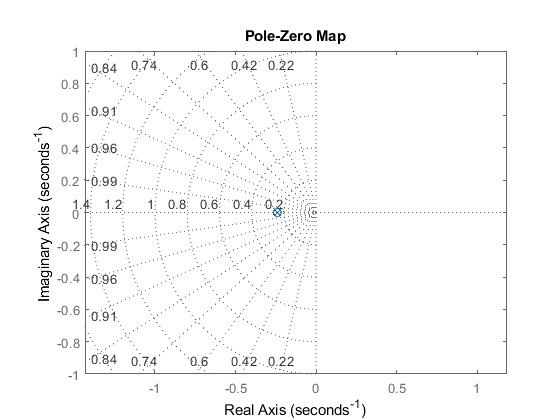

X = solucionesp(i, 1);
Y = solucionesp(i, 2);
W = solucionesp(i, 3);

expr  = subs(Gclr, [kp kd ki m b a], [X Y W m_val b_val a_val]);

% Separar numerador y denominador
[num, den] = numden(expr);

% Obtener coeficientes
num_coeffs = sym2poly(num);
den_coeffs = sym2poly(den);
        
% Crear la función de transferencia
G      = tf(num_coeffs, den_coeffs);
pzmap(G); grid on; axis('equal')

[P, Z] =  pzmap(G)

P =    -0.2400
   -0.2400


Z =    -0.2402
   -0.2398


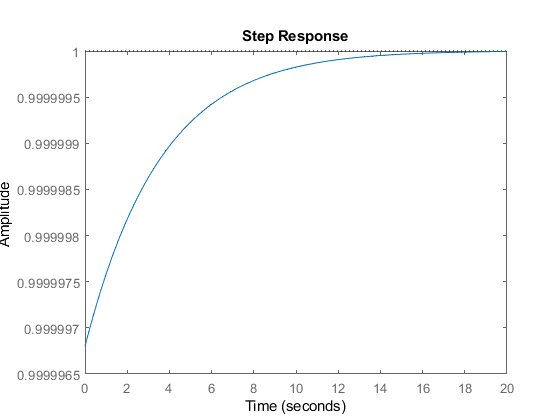

step(G)

Gu = subs(Gu, [m, a, b], [m_val, a_val, b_val])

$$Gu = \frac{10000}{1000\,s+200}$$

[numGu, denGu] = numden(Gu);
sysGu = tf(a_val*sym2poly(numGu)/b_val, sym2poly(denGu));


% Verificación de soluciones particulares con mapa de polos ceros polos
% distintos
i =2

i = 2

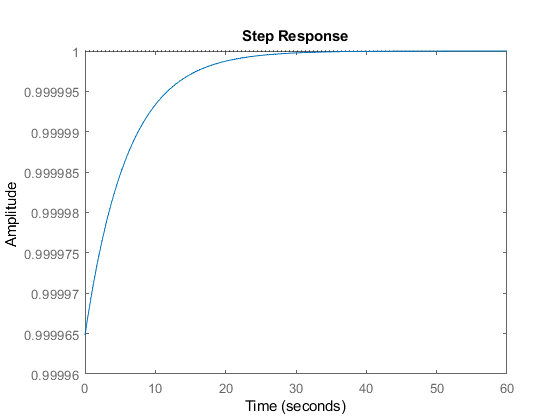


X = solucionesp12(i, 1);
Y = solucionesp12(i, 2);
W = solucionesp12(i, 3);

expr  = subs(Gclr, [kp kd ki m b a], [X Y W m_val b_val a_val]);

% Separar numerador y denominador
[num, den] = numden(expr);

% Obtener coeficientes
num_coeffs = sym2poly(num);
den_coeffs = sym2poly(den);
        
% Crear la función de transferencia
G      = tf(num_coeffs, den_coeffs);
step(G)

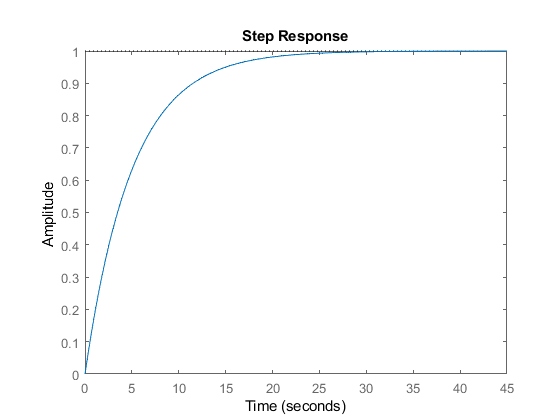

step(sysGu)

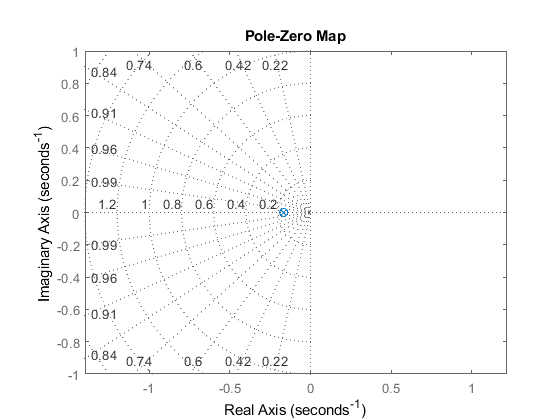

pzmap(G); grid on; axis('equal')